# DeconvolutionLab2 pruebas

javaaddpath([matlabroot filesep 'java' filesep 'DeconvolutionLab_2.jar']);

_______________________________________________________________________________________________________

## Cells 3D

cellimg = tiffreadVolume("cells3d.tif");
cellpsf = tiffreadVolume("cells3d_psf.tif");

cellimg = cellimg (119:190, 79:150, :);


cellresult = DL2.RL(cellimg, cellpsf, 30,'-out stack');

Log   	 238,17 us 	  150,1Mb  	 DeconvolutionLab2 2.1.2 (27.06.2018) on Matlab
Log   	 1407,58 us 	  176,6Mb  	 AcademicFFT Added
Log   	 4,14 ms 	  176,6Mb  	 JTransforms not found
Log   	 10,94 ms 	   62,0Mb  	 FFTW Widsom not found in : /Applications/MATLAB_R2024a.app/java/FFTW/
Log   	 12,10 ms 	   62,0Mb  	 FFTW Widsom not found in : /Applications/MATLAB_R2024a.app/java/
Log   	 12,57 ms 	   62,2Mb  	 FFTW Widsom not found in : /Users/yi/FFTW/
Log   	 12,71 ms 	   62,2Mb  	 FFTW Widsom not found in : /Users/yi/
Log   	 12,81 ms 	   62,2Mb  	 FFTW not found
Log   	 6,33 us 	   68,8Mb  	 Create Live Real Signal 


figure;
imshow(cellresult(:,:,55), []);
title('Deconvolved Result - Slice 1');

_______________________________________________________________________________________________________

## Cube of Spherical Beads

img = tiffreadVolume('cubeConvolved.tif');
img_b = tiffreadVolume('PSF.tif');

result = DL2.RL(img, img_b, 30,'-out stack');
figure;
imshow(result(:,:,64), []);
title('Deconvolved Result - Slice 64');
tiempo = 38.5;
% Imprimir el número con formato
fprintf('El tiempo es: %.2f s\n', tiempo);

______________________________________________________________________________________________________

## C. Elegans Embryo

function image_stack = load_image_stack(folder_path)
    % Listar todos los archivos en la carpeta y ordenar
    files = dir(fullfile(folder_path, '*.tif'));
    files = [files; dir(fullfile(folder_path, '*.png'))];
    files = [files; dir(fullfile(folder_path, '*.jpg'))];
    [~, index] = sort({files.name});
    files = files(index);
    
    % Leer la primera imagen para obtener las dimensiones
    first_image = imread(fullfile(folder_path, files(1).name));
    [height, width] = size(first_image);
    
    % Crear una matriz 3D vacía para almacenar las imágenes
    image_stack = zeros(height, width, length(files), class(first_image));
    
    % Cargar cada imagen en la matriz 3D
    for i = 1:length(files)
        image_stack(:, :, i) = imread(fullfile(folder_path, files(i).name));
    end
end

### Canal 1

% Ruta a la carpeta que contiene las imágenes Z-stack
imagePath1 = '/Users/yi/TFGNotebook/CElegans-CY3';
psfPath1 = '/Users/yi/TFGNotebook/PSF-CElegans-CY3';

% Cargar las imágenes en una matriz 3D
image_stack1 = load_image_stack(imagePath1);
psf_stack1 = load_image_stack(psfPath1);

% Recortar las matrices 3D a las dimensiones especificadas
image_stack1 = image_stack1(1:356, 1:336, :);
psf_stack1 = psf_stack1(179:534,169:504, :);

% Verificar las dimensiones de las matrices 3D
disp(size(image_stack1));

   356   336   104



disp(size(psf_stack1));

   356   336   104



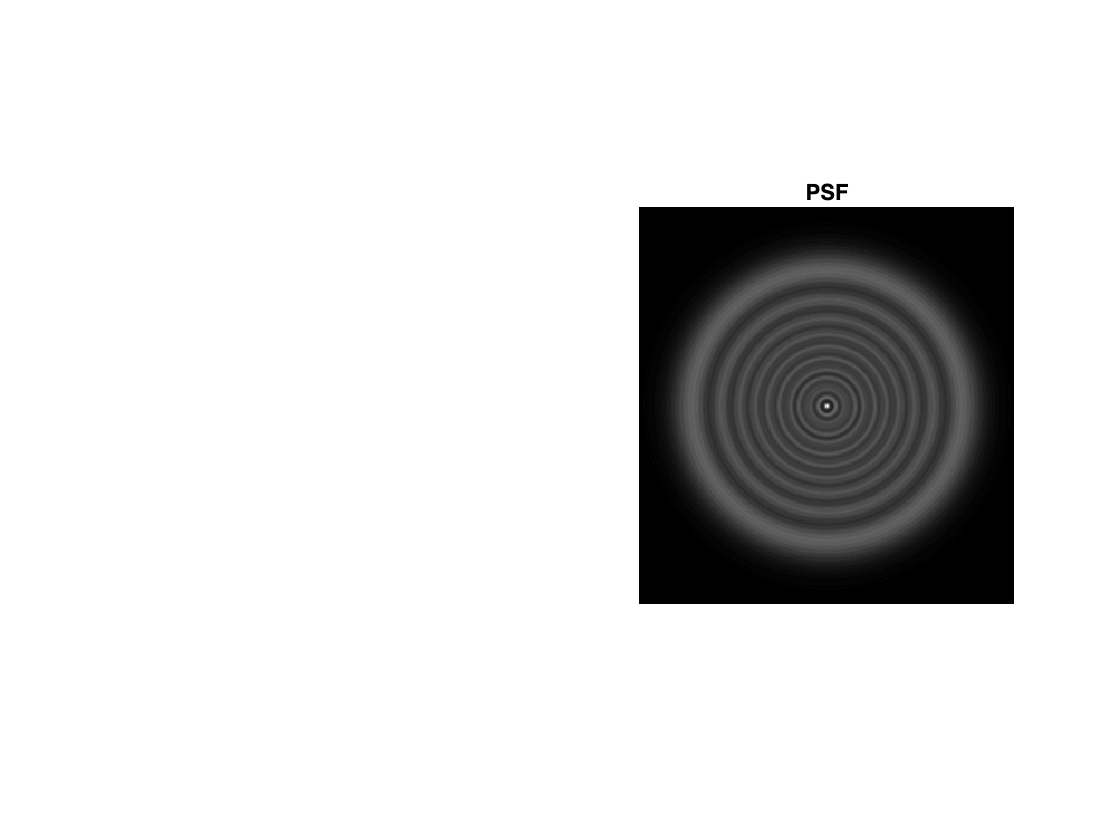

% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(psf_stack1(:, :, 1),[]);

% Añadir título
title('PSF');

% Desactivar los ejes
axis off;

channel1 = DL2.RL(image_stack1, psf_stack1, 50,'-out stack');

Log   	 882,33 us 	  249,7Mb  	 AcademicFFT Added
Log   	 12,48 ms 	  250,9Mb  	 JTransforms not found
Log   	 18,82 ms 	  260,8Mb  	 FFTW Widsom not found in : /Applications/MATLAB_R2024b.app/java/FFTW/
Log   	 20,35 ms 	  267,3Mb  	 FFTW Widsom not found in : /Applications/MATLAB_R2024b.app/java/
Log   	 20,98 ms 	  270,8Mb  	 FFTW Widsom not found in : /Users/yi/FFTW/
Log   	 21,32 ms 	  273,0Mb  	 FFTW Widsom not found in : /Users/yi/
Log   	 21,40 ms 	  273,0Mb  	 FFTW not found
Log   	 6,79 us 	  283,7Mb  	 Create Live Real Signal 


% Seleccionar el stack 52
stack_52 = channel1(:,:,52);

% Normalizar los valores para que estén en el rango [0, 255] si es necesario
stack_52_normalized = uint8(255 * mat2gray(stack_52)); % Escala a rango 0-255 y convierte a uint8

% Guardar el stack como archivo PNG
imwrite(stack_52_normalized, '50iter_DL2Channel1.png');
disp('Imagen guardada como stack_52_outputChannel1.png');

Imagen guardada como stack_52_outputChannel1.png


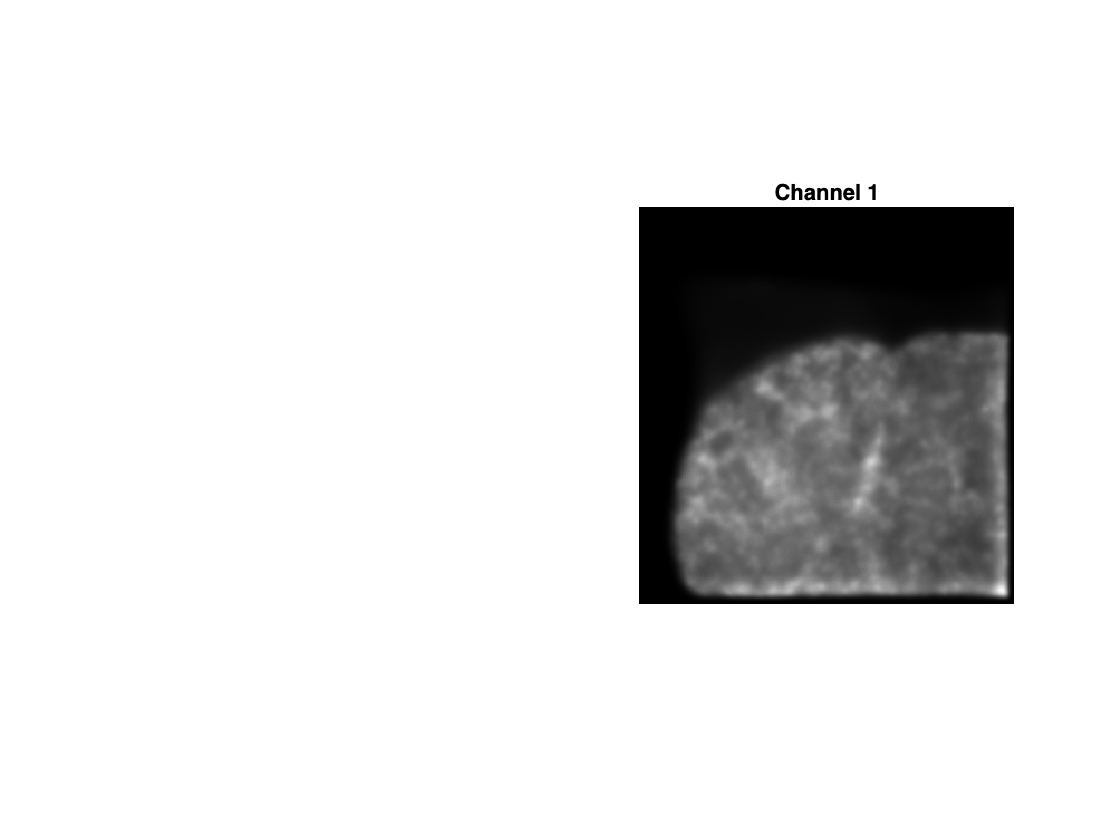

% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(channel1(:, :, 52),[]);

% Añadir título
title('Channel 1');

% Desactivar los ejes
axis off;

### Canal 2

% Ruta a la carpeta que contiene las imágenes Z-stack
imagePath2 = '/Users/yi/TFGNotebook/CElegans-DAPI';
psfPath2 = '/Users/yi/TFGNotebook/PSF-CElegans-DAPI';

% Cargar las imágenes en una matriz 3D
image_stack2 = load_image_stack(imagePath2);
psf_stack2 = load_image_stack(psfPath2);

% Recortar las matrices 3D a las dimensiones especificadas
image_stack2 = image_stack2(1:356, 1:336, :);
psf_stack2 = psf_stack2(204:508,184:488, :);

% Verificar las dimensiones de las matrices 3D
disp(size(image_stack2));

   356   336   104



disp(size(psf_stack2));

   305   305   104



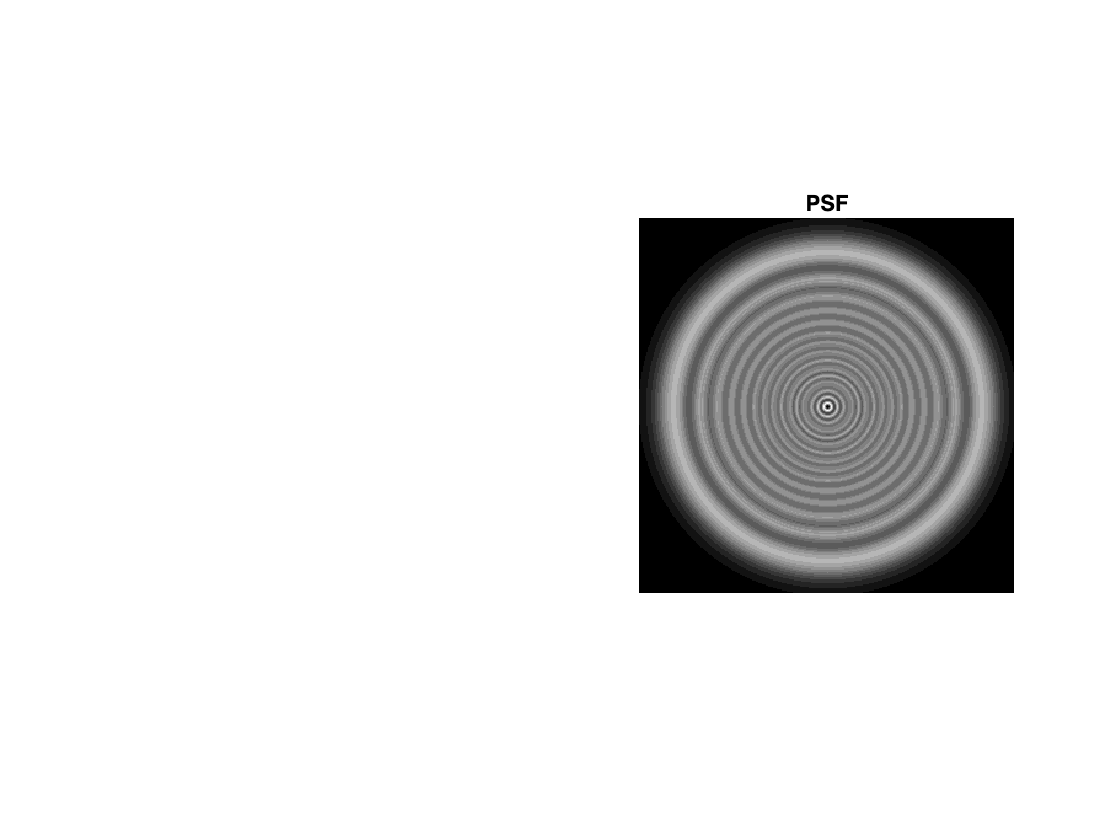


% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(psf_stack2(:, :, 1),[]);

% Añadir título
title('PSF');

% Desactivar los ejes
axis off;

channel2 = DL2.RL(image_stack2, psf_stack2, 50,'-out stack');

Log   	 21,46 us 	 1312,9Mb  	 Create Live Real Signal 


% Seleccionar el stack 52
stack_52 = channel2(:,:,52);

% Normalizar los valores para que estén en el rango [0, 255] si es necesario
stack_52_normalized = uint8(255 * mat2gray(stack_52)); % Escala a rango 0-255 y convierte a uint8

% Guardar el stack como archivo PNG
imwrite(stack_52_normalized, '50iter_DL2Channel2.png');
disp('Imagen guardada como stack_52_outputChannel2.png');

Imagen guardada como stack_52_outputChannel2.png


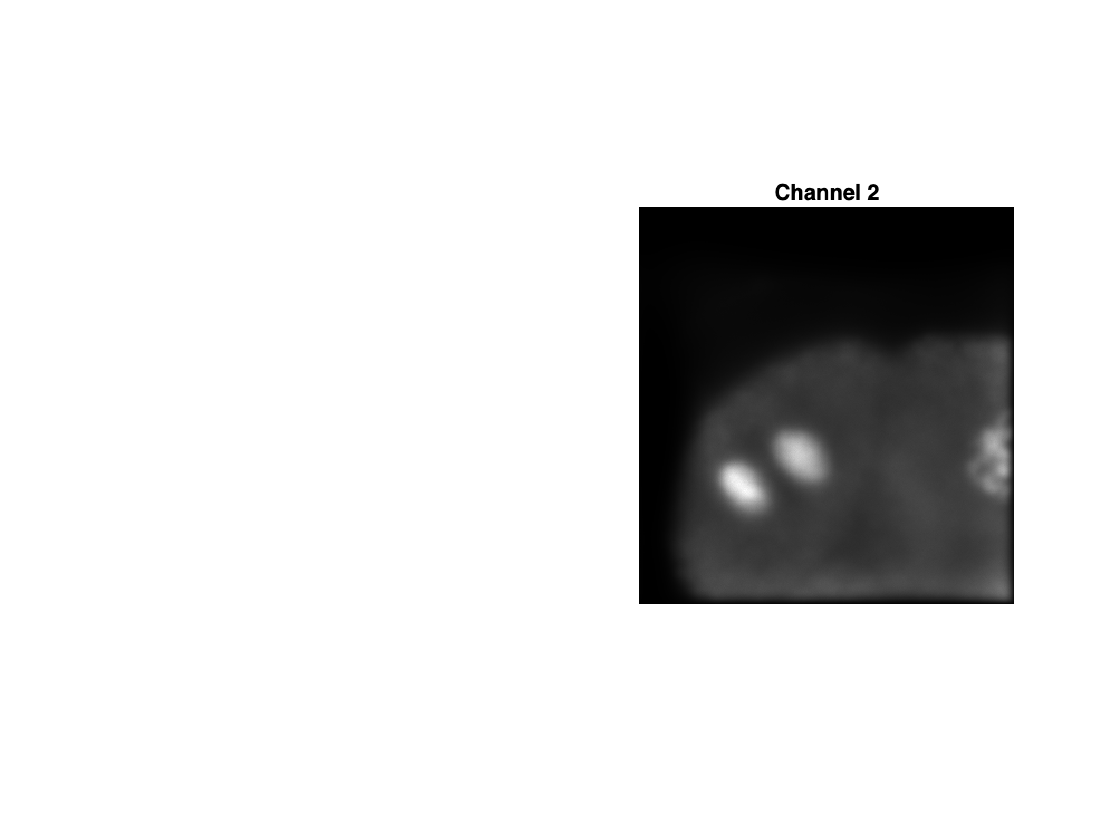


% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(channel2(:, :, 52),[]);

% Añadir título
title('Channel 2');

% Desactivar los ejes
axis off;

### Canal 3

% Ruta a la carpeta que contiene las imágenes Z-stack
imagePath3 = '/Users/yi/TFGNotebook/CElegans-FITC';
psfPath3 = '/Users/yi/TFGNotebook/PSF-CElegans-FITC';

% Cargar las imágenes en una matriz 3D
image_stack3 = load_image_stack(imagePath3);
psf_stack3 = load_image_stack(psfPath3);

% Recortar las matrices 3D a las dimensiones especificadas
image_stack3 = image_stack3(1:356, 1:336, :);
psf_stack3 = psf_stack3(204:508,184:488, :);

% Verificar las dimensiones de las matrices 3D
disp(size(image_stack3));

   356   336   104



disp(size(psf_stack3));

   305   305   104



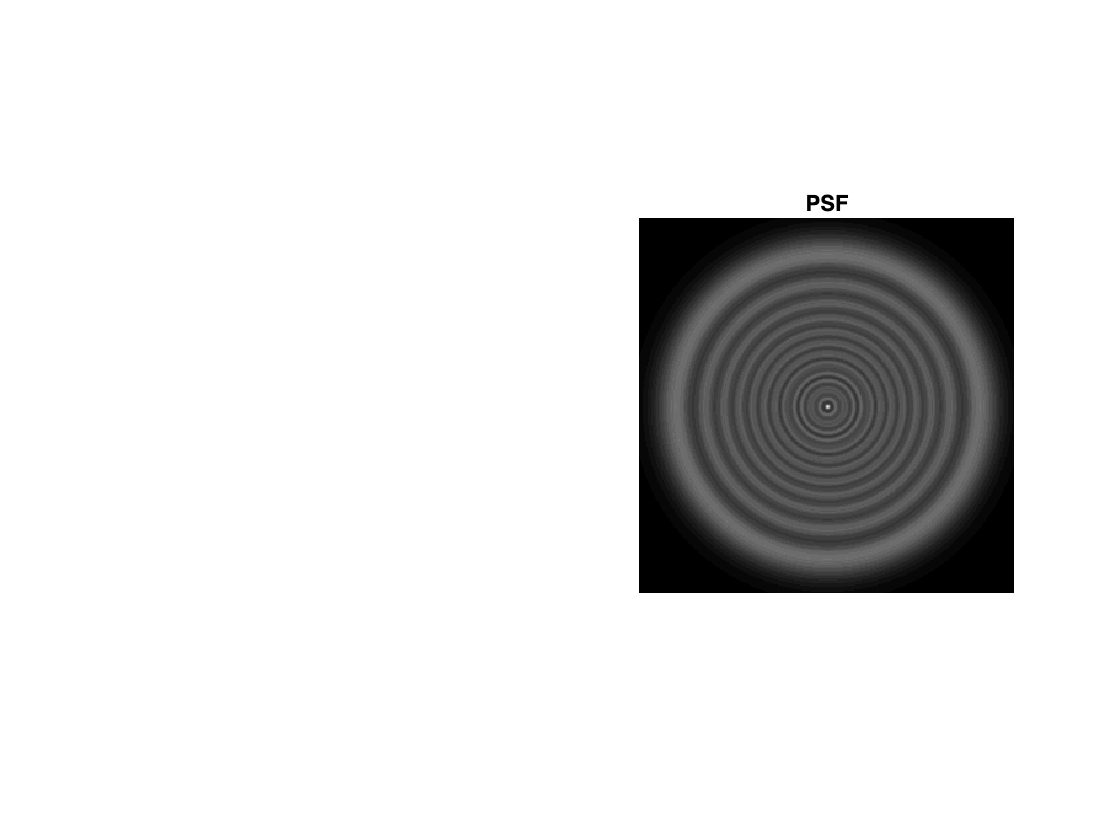



% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(psf_stack3(:, :, 1),[]);

% Añadir título
title('PSF');

% Desactivar los ejes
axis off;

channel3 = DL2.RL(image_stack3, psf_stack3, 50,'-out stack');

Log   	 2250,00 ns 	 1065,2Mb  	 Create Live Real Signal 


% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(channel3(:, :, 52),[]);

% Añadir título
title('Channel 3');

% Desactivar los ejes
axis off;

### Combinación de canales

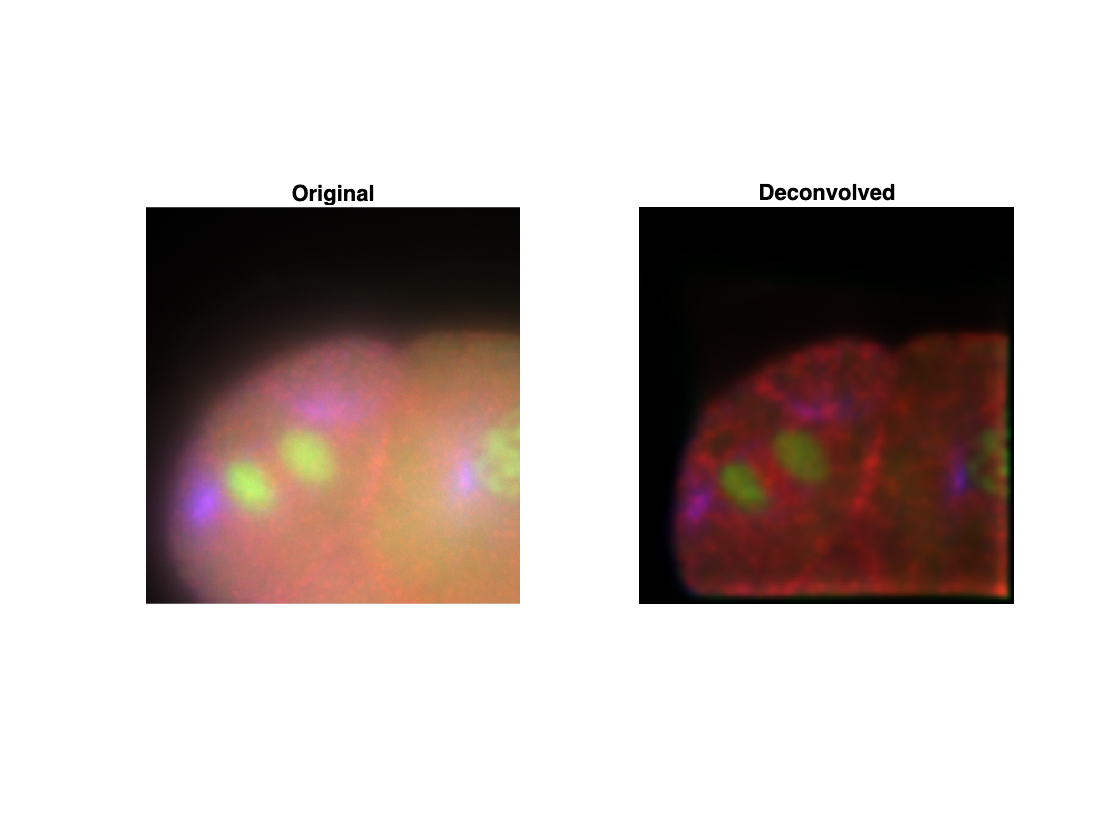

function normalized_image = normalize(image)
    min_val = double(min(image(:)));  % Convertir a double para evitar problemas con uint16
    max_val = double(max(image(:)));
    if min_val == max_val
        normalized_image = zeros(size(image), 'like', image);  % Usar el mismo tipo de datos
    else
        normalized_image = (double(image) - min_val) / (max_val - min_val);
    end
end

% Normalizar los canales (opcional, pero recomendado)
deconvolved_stack_R = normalize(channel1);
deconvolved_stack_G = normalize(channel2);
deconvolved_stack_B = normalize(channel3);

% Combinar los tres canales en una sola matriz 4D (altura, ancho, profundidad, canales)
deconvolved_stack_color = cat(4, deconvolved_stack_R, deconvolved_stack_G, deconvolved_stack_B);



% Visualizar un plano específico de la imagen deconvolucionada en color
figure;

subplot(1, 2, 1);
original_image_R = normalize(image_stack1(:, :, 52));
original_image_G = normalize(image_stack2(:, :, 52));
original_image_B = normalize(image_stack3(:, :, 52));
original_image_color = cat(3, original_image_R, original_image_G, original_image_B);
imshow(original_image_color);
title('Original');
axis off;

subplot(1, 2, 2);
deconvolved_image_color = squeeze(deconvolved_stack_color(:, :, 52, :));  % Convertir 4D a 3D para mostrar
imshow(deconvolved_image_color);
title('Deconvolved');
axis off;


% Guardar imagen PNG
imwrite(deconvolved_image_color, 'deconvolved_CElegans_deconvolutionLAB.png');